## PROBLEM 1.0

%{
ES 115 CLASS PROJECT PROBLEM 1.0
PROBLEM TITLE: Barometer Fluid Height Calculation
DESCRIPTION: This program calculates the height of a liquid column in a
             barometer for pressure ranging from 0 to 100 kPa. Two fluids are
             considered: water and mercury.
PURPOSE: To determine how the height of fluid column in a barometer varies
         with pressure and fluid density.
INPUTS:
    ~ P - Atmospheric pressure ranging from 0 to 100 kPa
    ~ rho - Density of the fluid (kg/m^3)
    ~ g - Acceleration due to gravity (m/s^2)
OUTPUTS:
    ~ h - Height of the liquid column (m)
ENGINNERING ALGORITHMS:
- Define pressure values from 0 to 100 kPa
- Convert pressure from kPa to Pa
- Define the densities of of mercury and water 
- Apply the barometer equation ( h = P / (rho * g))
- Calculate heights for both fluids
- Store the results in a two-dimensional array
MATLAB TOOLS/FUNCTIONS:
- Arrays
- Element wise operations
- Matrix construction
- Basic Arithmetic
%}

### 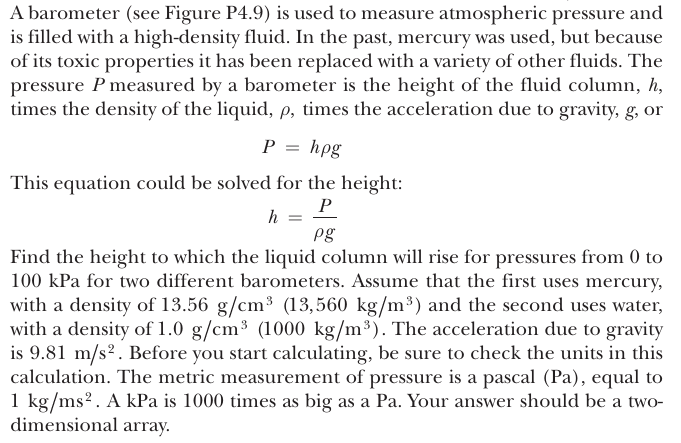       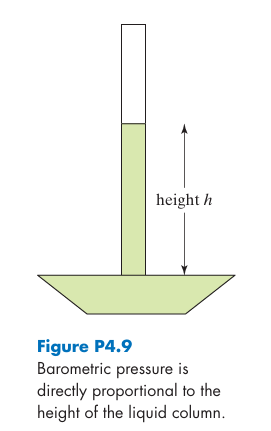

### **SOLUTION STEPS TO PROBLEM 1:**

- Define constants used and pressure range

- Convert Pressure to pascals from Kilo pascals

- Calculate height of the bars of each liquid

- Create a two dimensional array which displays the heights as a matrix

- Use the display function to display the results

%Constants
g = 9.81;           %Acceleration due to gravity
rho_mecury = 13560; %Density of mercury kg/m^3
rho_water = 1000;   %Density of water kg/m^3

P_kpa = 0:10:100;   %Displays pressure in increments of 10 from 0 to 100

P = P_kpa*1000;     %Converts pressure from kPa to pascals

h_mecury = P./(rho_mecury * g); %Calculates the heights of the columns
h_water = P./(rho_water * g);   %Calculates the heights of the columns

height_matrix = [h_mecury ; h_water]; %Creates a two dimensional array

% Display headings for liquid column heights
disp('Height of liquid column(meters)')
disp('Row 1: Mecury')
disp('Row 2: Water')
disp(height_matrix)